Входные параметры

close all;
clear variables;
tic; % замер времени

#### 1.1 Исходные данные

% параметры волны
f = 400*10^6;
c = 3*10^8;
lambda = c/f*10000; % 0.75 м %%% убрать 
% /1000/lambda % перевод мм в м + в дилнаях волн

Задаим количество точек

alpha = 0.5; % количество точек от необходимого количества
alpha_2 = 0.5;

% константы
k = 2*pi;
eta = 120*pi;
gamma = 1.781072417990;

% геометрические данные антенны
angle = 65;

#### 1.3. Расчет координат точек исходной фигуры

%% убрать
% lambda = 1000;

% исходные точки антенны
pl = struct('x', {}, 'y', {});
pl(1).x = 0/lambda;
pl(1).z = 0/lambda;
pl(2).x = 0/lambda;
pl(2).z = 14000/lambda;
pl(3).x = 7000/lambda;
pl(3).z = 14000/lambda;
pl(4).x = 7000/lambda;
pl(4).z = 0/lambda;

#### 1.3. Расчет координат точек окружностей

% точки окружностей
pc = struct('int1', {[]}, 'int2', {[]}, 'centr', {[]}, 'r', {[]});
pc(1).centr = [500, 13500]/lambda;
pc(1).r = 500/lambda;
pc(1).int1 = [0, 13500]/lambda;
pc(1).int2 = [500, 14000]/lambda;

pc(2).centr = [6500, 13500]/lambda;
pc(2).r = 500/lambda;
pc(2).int1 = [6500, 14000]/lambda;
pc(2).int2 = [7000, 13500]/lambda;

% исходные точки антенны
pli = struct('x', {}, 'y', {});
pli(1).x = 200/lambda;
pli(1).z = 0/lambda;
pli(2).x = 0/lambda;
pli(2).z = 13800/lambda;
pli(3).x = 6800/lambda;
pli(3).z = 13800/lambda;
pli(4).x = 6800/lambda;
pli(4).z = 0/lambda;

% точки окружностей
pci = struct('int1', {[]}, 'int2', {[]}, 'centr', {[]}, 'r', {[]});
pci(1).centr = [700, 13300]/lambda;
pci(1).r = 500/lambda;
pci(1).int1 = [200, 13500]/lambda;
pci(1).int2 = [700, 13800]/lambda;

pci(2).centr = [6300, 13300]/lambda;
pci(2).r = 500/lambda;
pci(2).int1 = [6300, 13800]/lambda;
pci(2).int2 = [6800, 13300]/lambda;

## Генерация контура основного

#### Задаим количество точек 

% Порядок точек
x1 = pl(1).x;
x2 = pc(1).int1(1);
x3 = pc(1).int2(1);
x4 = pc(2).int1(1);
x5 = pc(2).int2(1);
x6 = pl(4).x;
% 
z1 = pl(1).z;
z2 = pc(1).int1(2);
z3 = pc(1).int2(2);
z4 = pc(2).int1(2);
z5 = pc(2).int2(2);
z6 = pl(4).z; 

% длины отрезков каждого участков
l12 = sqrt((x1 - x2)^2 + (z1 - z2)^2);
l23 = 2*pi*pc(1).r;
l34 = sqrt((x3 - x4)^2 + (z3 - z4)^2);
l45 = 2*pi*pc(2).r;
l56 = sqrt((x5 - x6)^2 + (z5 - z6)^2);

% количество точек для расчета
N12 = ceil(l12)*100*alpha

N12 = 100

N23 = round(90/360*ceil(l23)*100*alpha)

N23 = 13

N34 = ceil(l34)*100*alpha

N34 = 50

N45 = round(90/360*ceil(l45)*100*alpha)

N45 = 13

N56 = ceil(l56)*100*alpha

N56 = 100


% cуммареное количество точек на антенне
N_l = 2*(N12 + N34 + N56) + 2*(N23 + N45); 

#### Получение контуро из функции

#### Параметры окружностей

% первая окружность (1/4 окружности)
phi_1_begin = 0; % относительно оси х
phi_1_end = 90;
dphi_1 = 90;

% вторая окружность 
phi_2_begin = 90; % относительно оси х
phi_2_end = 180;
dphi_2 = 90;

#### Построение окружностей

%%% Построим дугу окружности 1

R1 = pc(1).r;
t1 = zeros(1,N23);
% угловой шаг окружности
for i = 1 : N23
    phid_step = dphi_1/N23;
    t1 = phid_step*i;
    x23_r(i) = R1*cosd(-t1+180) + pc(1).centr(1);
    z23_r(i) = R1*sind(-t1+180) + pc(1).centr(2);
    dx23(i) = 2*R1*sind(phid_step/2);
end

%%% Построим дугу окружности 2
R2 = pc(2).r;
t2 = zeros(1,N45);
dx45 = zeros(1,N45);
% угловой шаг окружности
for i = 1 : N45
    phid_step = dphi_2/N45;
    t2 = phi_2_begin + phid_step*i;
    x45_r(i) = R2*cosd(-t2+180) + pc(2).centr(1);
    z45_r(i) = R2*sind(-t2+180) + pc(2).centr(2);
    dx45(i) = 2*R2*sind(phid_step/2);
end

%% УЧАСТОК_1 - наклонный участок
dx_12 = l12/N12;
x12 = zeros(1,N12);
z12 = zeros(1,N12);
dx12 = zeros(1,N12);
% заполнение масивов
for i = 1 : N12
    step23 = dx_12*i;
    x12(i) = x1;
    z12(i) = z1 + step23;
    dx12(i) = dx_12;
end

%% УЧАСТОК 2 - горизонтальный участок
dx_34 = l34/N34;
x34 = zeros(1,N34);
z34 = zeros(1,N34);
dx34 = zeros(1,N34);
% заполнение масивов
for i = 1 : N34
    step34 = dx_34*i;
    x34(i) = x3 + step34;
    z34(i) = z3;
    dx34(i) = dx_34;
end

%% УЧАСТОК 3 - вниз
dx_56 = l56/N56;
x56 = zeros(1,N56);
z56 = zeros(1,N56);
dx56 = zeros(1,N56);
for i = 1 : N56
    step56 = dx_56*i;
    x56(i) = x5;
    z56(i) = z5 - step56;
    dx56(i) = dx_56;
end

#### ОБЩИЙ DX

dx = horzcat(dx12, dx23, dx34, dx45, dx56);
dx = horzcat(dx, flip(dx));

#### 2.2 Вся антена (границы участков)

Антенная центры участков 

%% ПРЯМЫЕ
%% УЧАСТОК_1 - наклонный участок
x12_midle = zeros(1,N12);
z12_midle = zeros(1,N12);
for i = 1 : N12
    step23 = dx_12*(i-0.5);
    x12_midle(i) = x1;
    z12_midle(i) = z1 + step23;
end

%% УЧАСТОК 2 - горизонтальный участок
x34_midle = zeros(1,N34);
z34_midle = zeros(1,N34);
for i = 1 : N34
    step34 = dx_34*(i-0.5);
    x34_midle(i) = x3 + step34;
    z34_midle(i) = z3;
end

%% УЧАСТОК 3 - вниз
x56_midle = zeros(1,N56);
z56_midle = zeros(1,N56);
for i = 1 : N56
    step56 = dx_56*(i-0.5);
    x56_midle(i) = x5;
    z56_midle(i) = z5 - step56;
end

%% ОКРУЖНОСТИ
%%% Построим дугу окружности 1
t1 = zeros(1,N23);
for i = 1 : N23
    phid_step = dphi_1/N23;
    t1 = phid_step*(i-0.5);
    x23_midle(i) = R1*cosd(-t1+180) + pc(1).centr(1);
    z23_midle(i) = R1*sind(-t1+180) + pc(1).centr(2);
end

%%% Построим дугу окружности 2
t2 = zeros(1,N45);
for i = 1 : N45
    phid_step = dphi_2/N45;
    t2 = phi_2_begin + phid_step*(i-0.5);
    x45_midle(i) = R2*cosd(-t2+180) + pc(2).centr(1);
    z45_midle(i) = R2*sind(-t2+180) + pc(2).centr(2);
end

% АНТЕННА ПОД ЗЕМЛЕЙ центры участков
x_midle = [x12_midle, x23_midle, x34_midle, x45_midle,x56_midle];
z_midle = [z12_midle, z23_midle, z34_midle, z45_midle,z56_midle];
x_midle = horzcat(x_midle, flip(x_midle));
z_midle = horzcat(z_midle, flip(-z_midle));

#### 4.1 Касательные и нормали основного окнтура

#### 4.2. Посчитаем t для каждого отрезка

tx = zeros(1, N_l);
tz = zeros(1, N_l);
for i = 1 : N_l
    dx_cur = dx(i);
    if ismember(i, N_l) % проверка принадлежности массиву
        tx(i) = ((x_midle(i)-x_midle(i-1)))/dx_cur;
        tz(i) = ((z_midle(i)-z_midle(i-1)))/dx_cur;
    else
        tx(i) = (x_midle(i+1)-x_midle(i))/dx_cur;
        tz(i) = (z_midle(i+1)-z_midle(i))/dx_cur;
    end
end

#### 4.3. Посчитаем n для каждого отрезка

%  Посчитаем n для каждого отрезка
%  нормальный вектор найдем с помощью матрицы повороты
    alpha_m = -90;
    matrix = [cosd(alpha_m),-sind(alpha_m); sind(alpha_m),cosd(alpha_m)];

nx = zeros(1, N_l);
nz = zeros(1, N_l);
for i = 1 : N_l
     matrix_temp = [tx(i), tz(i)]*matrix;
     nx(i) = matrix_temp(1);
     nz(i) = matrix_temp(2);
end

casat = struct('tx', {zeros(1,N_l)}, 'tz', {zeros(1,N_l)}, 'nx', {zeros(1,N_l)}, 'nz', {zeros(1,N_l)});
for i = 1 : N_l
    casat(i).tx = tx(i);
    casat(i).tz = tz(i);
    casat(i).nx = nx(i);
    casat(i).nz = nz(i);
end

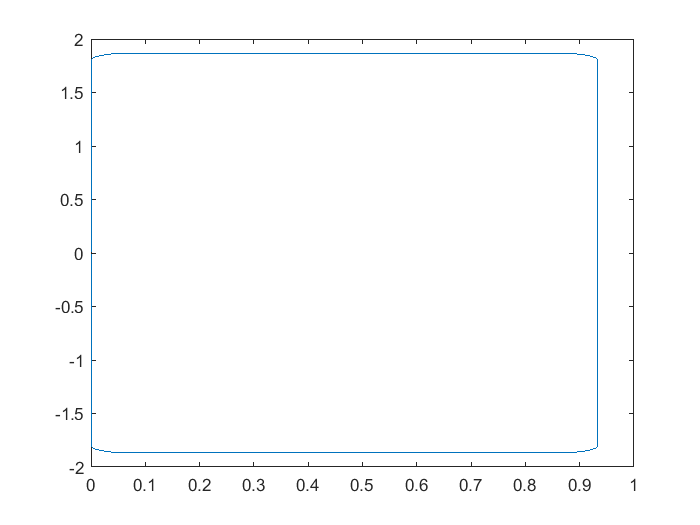

plot(x_midle, z_midle)

#### Для невязки

%% ПРЯМЫЕ
N12_DE = 2*N12;
N23_DE = 2*N23;
N34_DE = 2*N34;
N45_DE = 2*N45;
N56_DE = 2*N56;
N_l_DE = 2*N_l;

%% УЧАСТОК_1 - наклонный участок
x12_midle_DE = zeros(1,N12_DE);
z12_midle_DE = zeros(1,N12_DE);
dx_12_DE = l12/N12_DE;
for i = 1 : N12_DE
    step23 = dx_12_DE*i;
    x12_midle_DE(i) = x1;
    z12_midle_DE(i) = z1 + step23;
end

%% УЧАСТОК 2 - горизонтальный участок
x34_midle_DE = zeros(1,N34_DE);
z34_midle_DE = zeros(1,N34_DE);
dx_34_DE = l34/N34_DE;
for i = 1 : N34_DE
    step34 = dx_34_DE*i;
    x34_midle_DE(i) = x3 + step34;
    z34_midle_DE(i) = z3;
end

% УЧАСТОК 3 - вниз
dx_56_DE = l56/N56_DE;
x56_midle_DE = zeros(1,N56_DE);
z56_midle_DE = zeros(1,N56_DE);
for i = 1 : N56_DE
    step56 = dx_56_DE*i;
    x56_midle_DE(i) = x5;
    z56_midle_DE(i) = z5 - step56;
end

%% ОКРУЖНОСТИ
%%% Построим дугу окружности 1
t1 = zeros(1,N23_DE);
for i = 1 : N23_DE
    phid_step = dphi_1/N23_DE;
    t1 = phid_step*i;
    x23_midle_DE(i) = R1*cosd(-t1+180) + pc(1).centr(1);
    z23_midle_DE(i) = R1*sind(-t1+180) + pc(1).centr(2);
end

%%% Построим дугу окружности 2
t2 = zeros(1,N45_DE);
for i = 1 : N45_DE
    phid_step = dphi_2/N45_DE;
    t2 = phi_2_begin + phid_step*i;
    x45_midle_DE(i) = R2*cosd(-t2+180) + pc(2).centr(1);
    z45_midle_DE(i) = R2*sind(-t2+180) + pc(2).centr(2);
end

% АНТЕННА ПОД ЗЕМЛЕЙ центры участков
x_midle_DE = [x12_midle_DE, x23_midle_DE, x34_midle_DE, x45_midle_DE, x56_midle_DE];
z_midle_DE = [z12_midle_DE, z23_midle_DE, z34_midle_DE, z45_midle_DE, z56_midle_DE];
x_midle_DE = horzcat(x_midle_DE, flip(x_midle_DE));
z_midle_DE = horzcat(z_midle_DE, flip(-z_midle_DE));

for i = 1 : N_l_DE
    dx12_DE(i) = dx_12;
    dx34_DE(i) = dx_34;
    dx56_DE(i) = dx_56;
    dx23_DE(i) = 2*R1*sind(dphi_1/N23_DE/2);
    dx45_DE(i) = 2*R2*sind(dphi_2/N45_DE/2);
end

dx_DE = horzcat(dx12_DE, dx23_DE, dx34_DE, dx45_DE, dx56_DE);
dx_DE = horzcat(dx_DE, flip(dx_DE));

tx_DE = zeros(1, N_l_DE);
tz_DE = zeros(1, N_l_DE);

for i = 1 : N_l_DE
    dx_cur = dx_DE(i);
    if ismember(i, N_l_DE) % проверка принадлежности массиву
        tx_DE(i) = ((x_midle_DE(i)-x_midle_DE(i-1)))/dx_cur;
        tz_DE(i) = ((z_midle_DE(i)-z_midle_DE(i-1)))/dx_cur;
    else
        tx_DE(i) = (x_midle_DE(i+1)-x_midle_DE(i))/dx_cur;
        tz_DE(i) = (z_midle_DE(i+1)-z_midle_DE(i))/dx_cur;
    end
end

#### Построение вспомогательного контура

Антенная центры участков 

% Порядок точек
x1 = pli(1).x;
x2 = pci(1).int1(1);
x3 = pci(1).int2(1);
x4 = pci(2).int1(1);
x5 = pci(2).int2(1);
x6 = pli(4).x;
% 
z1 = pli(1).z;
z2 = pci(1).int1(2);
z3 = pci(1).int2(2);
z4 = pci(2).int1(2);
z5 = pci(2).int2(2);
z6 = pli(4).z; 

% длины отрезков каждого участков
l12 = sqrt((x1 - x2)^2 + (z1 - z2)^2);
l23 = 2*pi*pc(1).r;
l34 = sqrt((x3 - x4)^2 + (z3 - z4)^2);
l45 = 2*pi*pc(2).r;
l56 = sqrt((x5 - x6)^2 + (z5 - z6)^2);

% зададим число точек
% количество точек для расчета
N12_i = round(N12*alpha_2)

N12_i = 50

N23_i = round(N23*alpha_2)

N23_i = 7

N34_i = round(N34*alpha_2)

N34_i = 25

N45_i = round(N45*alpha_2)

N45_i = 7

N56_i = round(N56*alpha_2)

N56_i = 50


% cуммареное количество точек на антенне
N_i = 2*(N12_i + N34_i + N56_i) + 2*(N23_i + N45_i); 

R1 = pci(1).r;
% угловой шаг окружности
for i = 1 : N23_i
    phid_step = dphi_1/N23_i;
    t1 = phid_step*(i-0.5);
    x23_midle_i(i) = R1*cosd(-t1+180) + pci(1).centr(1);
    z23_midle_i(i) = R1*sind(-t1+180) + pci(1).centr(2);
end

%% Построим дугу окружности 2
R2 = pci(2).r;
t2 = zeros(1,N45_i);
% угловой шаг окружности
for i = 1 : N45_i
    phid_step = dphi_2/N45_i;
    t2 = phi_2_begin + phid_step*(i-0.5);
    x45_midle_i(i) = R2*cosd(-t2+180) + pci(2).centr(1);
    z45_midle_i(i) = R2*sind(-t2+180) + pci(2).centr(2);
end


#### 2.1 Антена над землей

%% УЧАСТОК_1 - наклонный участок
dx_12 = l12/N12_i;
x12_midle_i = zeros(1,N12_i);
z12_midle_i = zeros(1,N12_i);
% заполнение масивов
for i = 1 : N12_i
    step23 = dx_12*(i-0.5);
    x12_midle_i(i) = x1;
    z12_midle_i(i) = z1 + step23;
end

%% УЧАСТОК 2 - горизонтальный участок
dx_34 = l34/N34_i;
x34_midle_i = zeros(1,N34_i);
z34_midle_i = zeros(1,N34_i);
% заполнение масивов
for i = 1 : N34_i
    step34 = dx_34*(i-0.5);
    x34_midle_i(i) = x3 + step34;
    z34_midle_i(i) = z3;
end

%% УЧАСТОК 3 - вниз
dx_56 = l56/N56_i;
x56_midle_i = zeros(1,N56_i);
z56_midle_i = zeros(1,N56_i);
for i = 1 : N56_i
    step56 = dx_56*(i-0.5);
    x56_midle_i(i) = x5;
    z56_midle_i(i) = z5 - step56;
end

x_midle_i = [x12_midle_i, x23_midle_i, x34_midle_i, x45_midle_i, x56_midle_i];
z_midle_i = [z12_midle_i, z23_midle_i, z34_midle_i, z45_midle_i, z56_midle_i];
x_midle_i = horzcat(x_midle_i, flip(x_midle_i));
z_midle_i = horzcat(z_midle_i, flip(-z_midle_i));

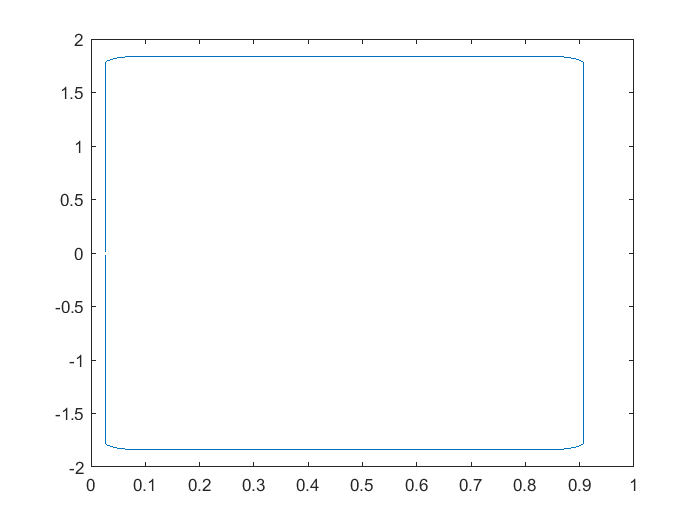

plot(x_midle_i, z_midle_i)

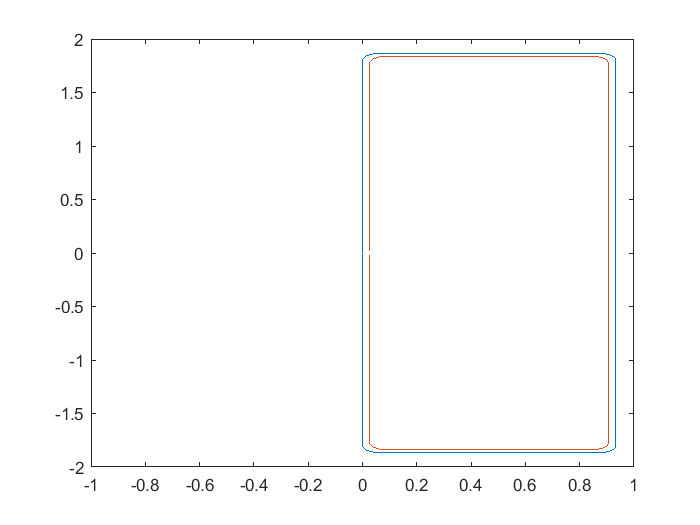

plot(x_midle, z_midle, x_midle_i, z_midle_i)

xlim([-1, 1])
ylim([-2, 2])

## Расчет излучателя

#### 1.5. Расчет координат излучателя

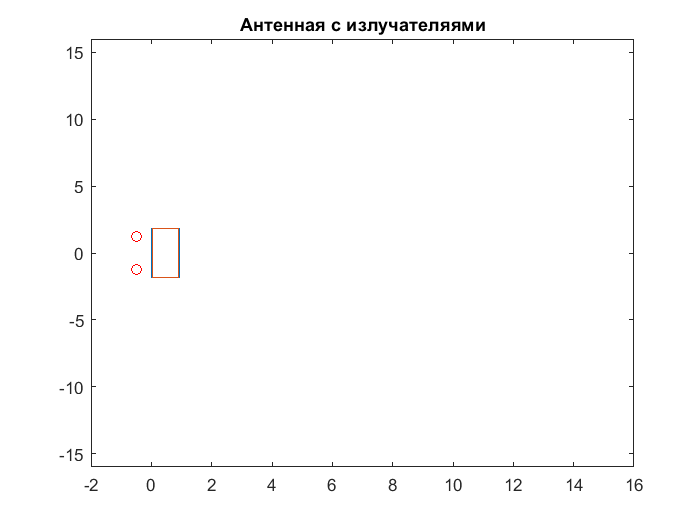

% паарметры расположения
l_antenn = 5000/lambda; %%% убрать
h_antenn = 1/2; %%% убрать

% координаты самого излучателя
x1_antenn = - h_antenn;
z1_antenn = pl(2).z - l_antenn;

x2_antenn = x1_antenn;
z2_antenn = -z1_antenn;

plot(x_midle, z_midle, x_midle_i, z_midle_i, x1_antenn, z1_antenn, 'ro', x2_antenn, z2_antenn, 'ro');
xlim([-2.00 16.00])
ylim([-16 16.0])
title('Антенная с излучателяями')

#### 5.1. Падающее поле

% излучаель создает магнитное поле 
Ei = zeros(N_l,1);
Hi = zeros(N_l,1);
% падающее поле 
for m = 1 : N_l
    xm = x_midle(m);
    zm = z_midle(m);
    txm = casat(m).tx;
    tzm = casat(m).tz;
    
    % растояния 
    r1 = ((xm-x1_antenn)^2 + (zm-z1_antenn)^2);
    r2 = ((xm-x2_antenn)^2 + (zm-z2_antenn)^2);
    
    % Падающее магнитное поле
    Hi(m) = besselh(0,1,k*r1) + besselh(0,1,k*r2);
    
    Ex = -1i*(zm-z1_antenn)*besselh(1,1,k*r1)/r1...
         -1i*(zm-z2_antenn)*besselh(1,1,k*r2)/r2;
     
    Ez = +1i*(xm-x1_antenn)*besselh(1,1,k*r1)/r1...
         +1i*(xm-x2_antenn)*besselh(1,1,k*r2)/r2;
    % Касательное электрическое поле
    Ei(m) = Ex*txm + Ez*tzm;
end  

#### Сам алгоритм MAS

Hs = zeros(N_l,N_i);
Es = zeros(N_l,N_i);
for m = 1 : N_l
    xm = x_midle(m);
    zm = z_midle(m);
    txm = casat(m).tx;
    tzm = casat(m).tz;
    
    %пробегаемся по всем точкам ВИ
    for n = 1 : N_i
        xn = x_midle_i(n);
        zn = z_midle_i(n);
        
        xmn = xm - xn;
        zmn = zm - zn;
        rmn = sqrt(xmn^2 + zmn^2);
               
        Es(m,n) = besselh(1,1,k*rmn)*(xmn*tzm - zmn*txm)/rmn;
    end
end


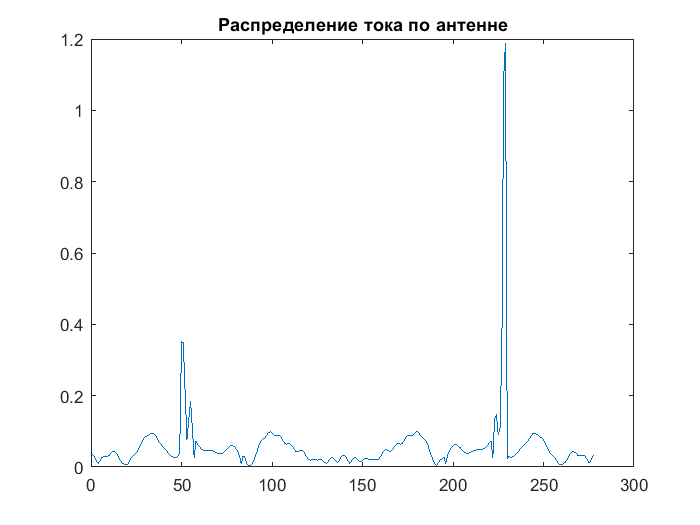

% расчеток токов ВИ 
% I=Hs\Hi;
I=Es\Ei;

plot(1:length(I), abs(I));
title("Распределение тока по антенне")

#### 6.1. Где смотрим поле

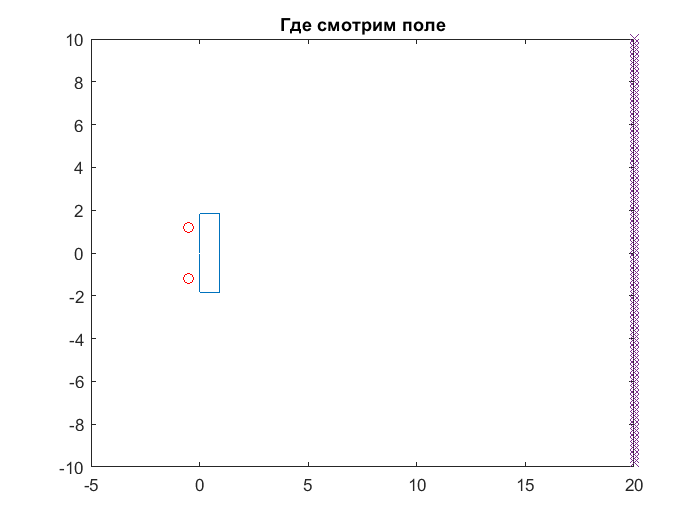

l = 150*10^3/lambda;
N_point = 100;
l_begin = -10;
l_end = 10;

x_see = zeros(1, N_point);
z_see = zeros(1, N_point);
for i = 1 : N_point
    step_see = (l_end - l_begin)/N_point;
    
    x_see(i) = l;
    z_see(i) = l_begin + step_see*i;
end

figure;
plot(x_midle,z_midle,x1_antenn,z1_antenn, '-ro', x2_antenn, z2_antenn, '-ro', x_see, z_see, 'x');
title('Где смотрим поле'); 

#### 6.2. Поле на растоянии без антенны

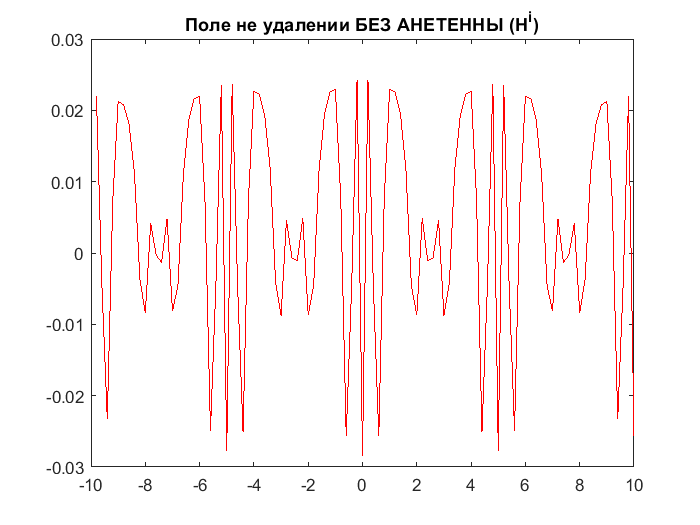

Hi_without_antenn = zeros(1,N_point);
for m = 1 : N_point
    xm = x_see(m);
    zm = z_see(m);
    r1 = ((xm-x1_antenn)^2 + (zm-z1_antenn)^2);
    r2 = ((xm-x2_antenn)^2 + (zm-z2_antenn)^2);
    
    Hi_without_antenn(m) = besselh(0,1,k*r1) + besselh(0,1,k*r2);
end

figure;
plot(z_see, real(Hi_without_antenn), 'r');
title('Поле не удалении БЕЗ АНЕТЕННЫ (H^i)'); 

#### 6.2. Поле на растоянии с антеной

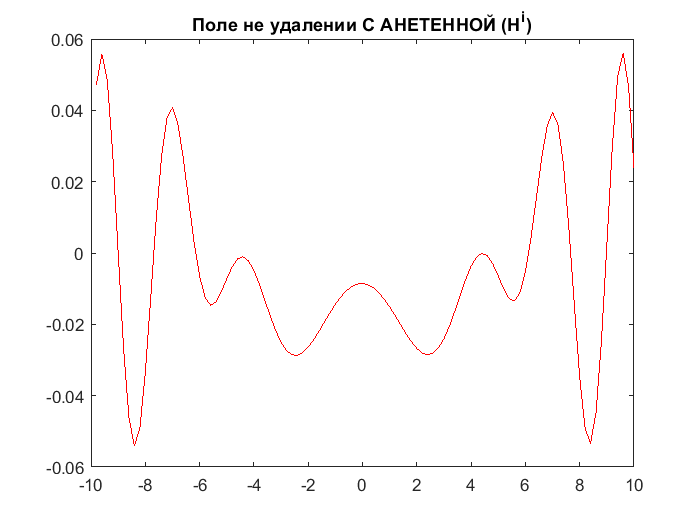

H_surf = zeros(1,N_point);
for m = 1 : N_point
    xm = x_see(m);
    zm = z_see(m);
    
    h_surf = 0;
    for n = 1 : N_i
        xn = x_midle_i(n);
        zn = z_midle_i(n);
        rmn = sqrt((xn-xm)^2 + (zn-zm)^2);
                
        h_surf = h_surf + I(n,1)*besselh(0,1,k*rmn);
    end
    H_surf(m) = h_surf;
end

figure;
fig = plot(z_see, real(H_surf), 'r');
title('Поле не удалении C АНЕТЕННОЙ (H^i)'); 

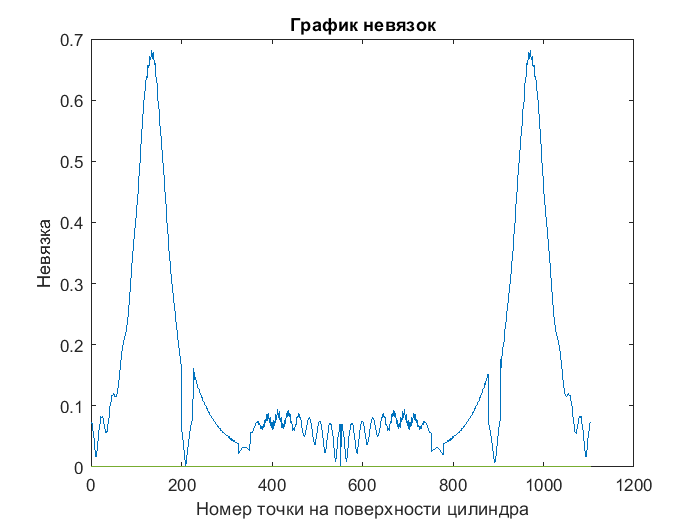

%% НЕВЯЗКА
dE = zeros(1, 2*N_l );
[xm,zm,txm,tzm,E_DE_sum,n,m,xn,zn,xmn,zmn,rmn,Ex,Ez,Es_DE...
    phi_grad, cx,cz,Eix,Eiz, Ei_DE] = deal(0);

for m = 1 : N_l_DE
    xm = x_midle_DE(m);
    zm = z_midle_DE(m);
    txm = tx_DE(m);
    tzm = tz_DE(m);
    
    E_DE_sum = 0;    
    for n = 1 : N_i
        xn = x_midle_i(n);
        zn = z_midle_i(n);    
                  
        xmn = xm - xn;
        zmn = zm - zn;
        rmn = sqrt(xmn^2 + zmn^2);
            
        Ex = + 1i*zmn*besselh(1,1,k*rmn)/rmn;
        Ez = - 1i*xmn*besselh(1,1,k*rmn)/rmn;
        Es_DE = Ex*txm + Ez*tzm;
          
        % суммарное поле от ВИ в точке m
        E_DE_sum = E_DE_sum + I(n)*Es_DE;
    end
    
    Eix = -1i*(zm-z1_antenn)*besselh(1,1,k*r1)/r1...
         -1i*(zm-z2_antenn)*besselh(1,1,k*r2)/r2;
    Eiz = +1i*(xm-x1_antenn)*besselh(1,1,k*r1)/r1...
         +1i*(xm-x2_antenn)*besselh(1,1,k*r2)/r2;
    % Касательное электрическое поле
    Ei_DE = Eix*txm + Eiz*tzm;
    
    % cам расчет невязки
    dE(m,1) =  abs(Ei_DE - E_DE_sum);
end    
    
% график для невязки
figure;
plot(1:length(dE),dE);
title('График невязок'); 
xlabel('Номер точки на поверхности цилиндра'); 
ylabel('Невязка');